# **Standing wave dispersion simulation **

clear
clc

`현재 위치 설정 및 경로추가

cd 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703'
addpath 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703\data'

랜덤 방식 설정

rng('shuffle'); % Seed the random number generator based on the current time

vx_tilt_list = [6]

vx_tilt_list = 6

for vx_tilt_ind = 1:numel(vx_tilt_list)

기본 상수 설정

load("STN_constants.mat"); %load default constants
%you can re-define contants here!
vx_caused_tilted=vx_tilt_list(vx_tilt_ind)

vx_caused_tilted = 6

세기(I) 리스트 작성

%I1, I2 setting (I1과 I2의 행렬 크기를 같게 하세요.)

%1.2mJ
% I1_list = [0.1 0.2 0.3 0.4 0.6 1.2]*0.65;
% I2_list = [14.4 7.2 4.8 3.6 2.4 1.2]*0.65;

%1.4mJ
% I1_list = [0.1 0.2 0.4 0.5 0.7 0.8 1.4]*0.65;
% I2_list = [19.6 9.8 4.9 3.92 2.8 2.45 1.4]*0.65;

%1.6mJ
% I1_list = [0 0.1 0.2 0.25 0.4 0.8 1.6]*0.7;
% I2_list = [0 25.6 12.8 10.2 6.4 3.2 1.6]*0.7;

%SW
I1_list = [0:0.05:5];
I2_list = [0:0.05:5];

% off 
% I1_list = [0];
% I2_list = [0];
Cell_velocity=cell(numel(I2_list),1);

Trajectory calculation.

for I_ind = 1:numel(I2_list)
run('Main_code.m') %Main code returns the velocity of x,y,z
% run('Main_code_CUDA.m') %Main code returns the velocity of x,y,z
Cell_velocity{I_ind}=velocity;% Cell_velocity(intensity list) = velocity of particle, 
end

Elapsed time is 7.011234 seconds.
Elapsed time is 7.450360 seconds.
Elapsed time is 7.182233 seconds.
Elapsed time is 7.838239 seconds.
Elapsed time is 7.791550 seconds.
Elapsed time is 7.332003 seconds.
Elapsed time is 7.244557 seconds.
Elapsed time is 7.222944 seconds.
Elapsed time is 7.245887 seconds.
Elapsed time is 7.364518 seconds.
Elapsed time is 7.390820 seconds.
Elapsed time is 7.437750 seconds.
Elapsed time is 7.279116 seconds.
Elapsed time is 7.479575 seconds.
Elapsed time is 7.235209 seconds.
Elapsed time is 7.221826 seconds.
Elapsed time is 7.283500 seconds.
Elapsed time is 7.214702 seconds.
Elapsed time is 7.315779 seconds.
Elapsed time is 7.325449 seconds.
Elapsed time is 7.307544 seconds.
Elapsed time is 7.323638 seconds.
Elapsed time is 7.292379 seconds.
Elapsed time is 7.277066 seconds.
Elapsed time is 7.320266 seconds.
Elapsed time is 7.318362 seconds.
Elapsed time is 7.330487 seconds.
Elapsed time is 7.347259 seconds.
Elapsed time is 7.340259 seconds.
Elapsed time i

Image blurring 상수 설정

vel_pix=2.28; %픽셀당 속도
rep_std=4.0; %electron repulsion standard deviation
rep_vel=2.7; %electron repulsion speed standard deviation

Image blurring (z축 방향으로는 계산안함)

run('Image_code_voigt.m')

plotting

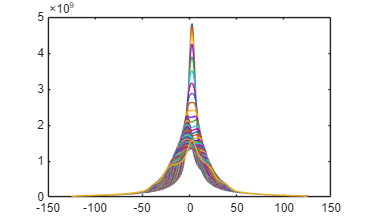

plot(xgrid,sumx)

Save

%making the data saved
constants = struct();
constants.I1_list = I1_list;
constants.I2_list = I2_list;
constants.lambda = lambda;
constants.MAX = MAX;
constants.tend = tend;
constants.tstep = tstep;
constants.vx_caused_tilted = vx_caused_tilted;
constants.vel_pix=vel_pix;
constants.Dye_sigma=Dye_sigma;
constants.w0z = w0z;
constants.w0y = w0y;
constants.jm_data  = jm_data;
% constants.x_init_distribution = x_init_distribution;
constants.x_init_vel_sigma= x_init_vel_sigma;
constants.y_init_vel_sigma= y_init_vel_sigma; 
constants.z_init_vel_sigma = z_init_vel_sigma;
constants.z_init_vel_off = z_init_vel_off;
constants.Dye_tau=Dye_tau;
constants.Ips_z = Ips_z;
constants.Ips_y = Ips_y;
constants.Ij_distribution = Ij_distribution;

data = struct();
data.xgrid=xgrid';
data.ygrid=ygrid';
data.img_matrix=img_matrix;
data.sumx=sumx;
data.sumy=sumy;

filename=sprintf("data_SW_20251202_%2.0f.mat",vx_tilt_ind)

save(filename,'data','I1_list','I2_list','Cell_velocity','constants');

filename = "data_SW_20251202_ 1.mat"

end